# test_fftfunc function

this demo is used to test fftfunc function. 

fftfunc is a function to output amplitude and frequency of a time-strain signal by fft. 

close all;
% clear
%  DEBUG ! ! !
dbstop if error;
format long

addpath ../include/model_dataprocessing ..\include\model_eventdetection

addpath(genpath('../../../include'));

filename = '..\..\testdata\strainMat166_188.mat';

filename = '..\..\testdata\strainMat61.mat';

filename = '..\..\testdata\strainMat44.mat';

filename = '..\..\testdata\strainMat103.mat';

strainMat = importdata(filename);
arr = 164:2:188; 
count0 = 143;

## #1: fft for original strain data.

get das original signal.

% filename = getfilenamelist('.das', 'on');

get original das strain data. 

% [strainMat, position, time] = readdasdata(dasdataformat, filename);
% strainMat([1:7, 79, 80], :) = 3e-4*randn(9, length(time));

[lenPosition, lenTime] = size(strainMat);
time = (1:lenTime)*0.064; position = 1:lenPosition;

a 3D figure of original signal.

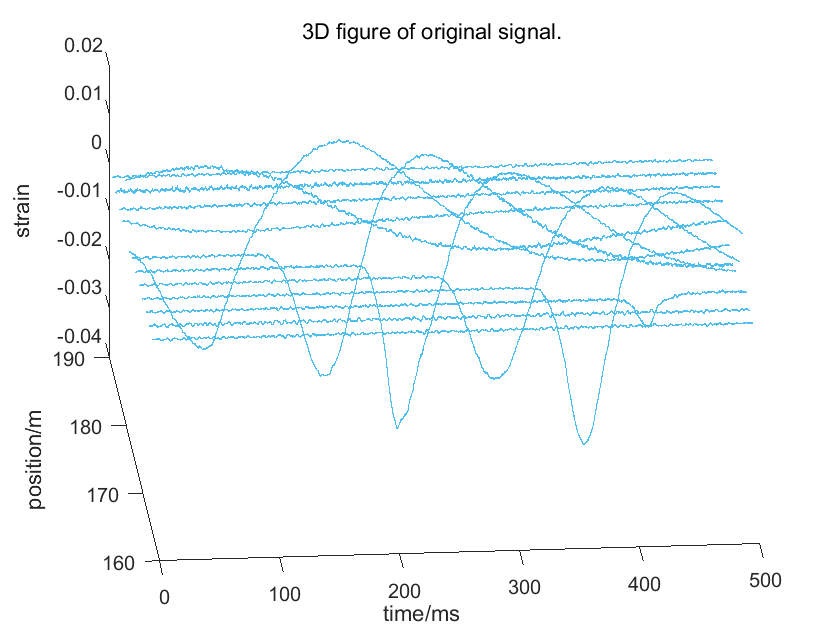

ax1 = axes(figure); 
plot3D(ax1, strainMat(arr, :), position(arr), time, []);   title(ax1, '3D figure of original signal. ');

view([-4.7960 34.8802])

We take the fast Fourier transform of the strain data

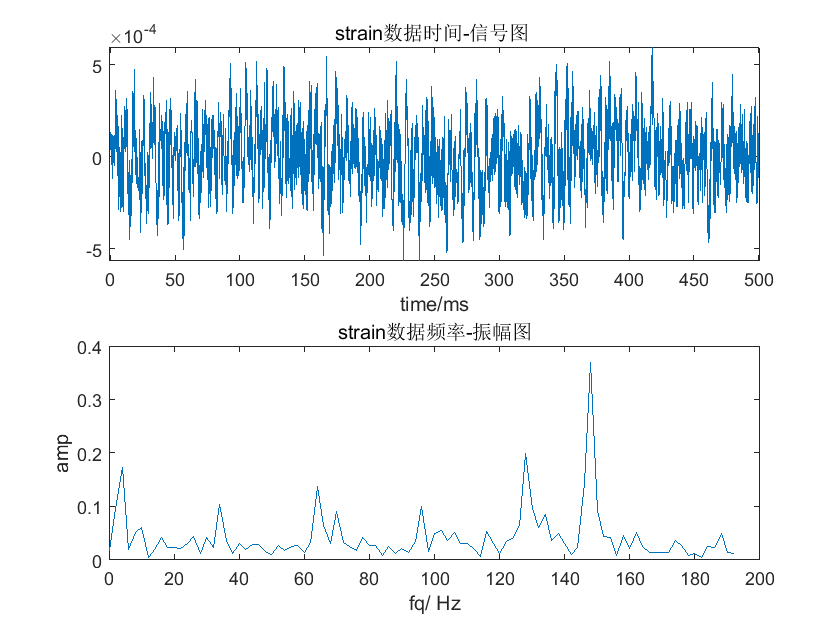

[ampMat0, frequencyArray0, ~] = fftfunc(strainMat(count0, :), time, 'strain');

## #2: fft for filtered strain data.

filtering the das strain data. 

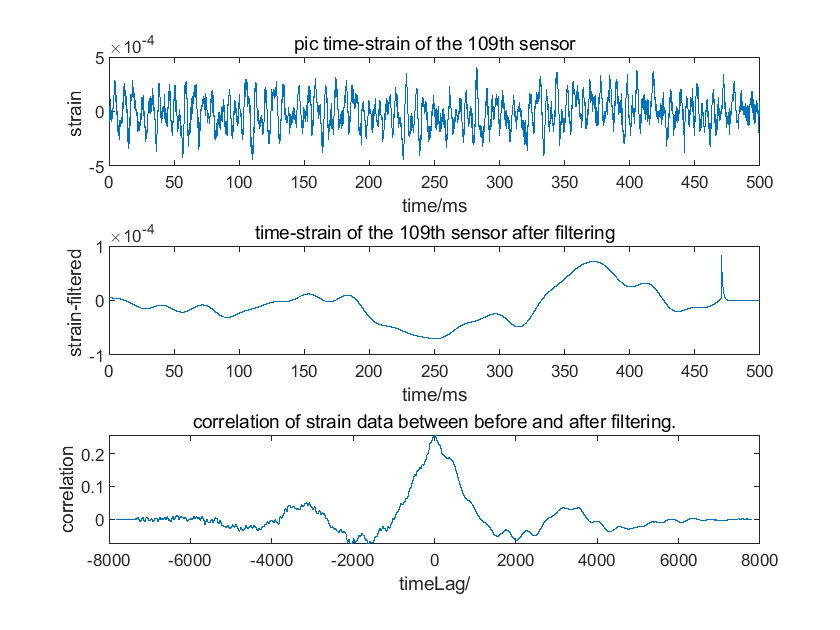

fp.wp = 20;    fp.ws = 40;
[strainFilterMat, timeLag, maxCorr, fig] = filteringfunc(strainMat, time, fp);

time lag and correlation. 

tc = [timeLag(arr), maxCorr(arr)]

tc =  -21.000000000000000   0.241722917382846
  -1.000000000000000   0.287707051314240
  -2.000000000000000   0.941158157533127
  -8.000000000000000   0.994955475128342
  -2.000000000000000   0.998016429867971
                   0   0.996728564569458
                   0   0.999631080425486
  -2.000000000000000   0.999663338729144
  -2.000000000000000   0.996650047873599
                   0   0.997628176654694


a 3D figure of filtered signal.

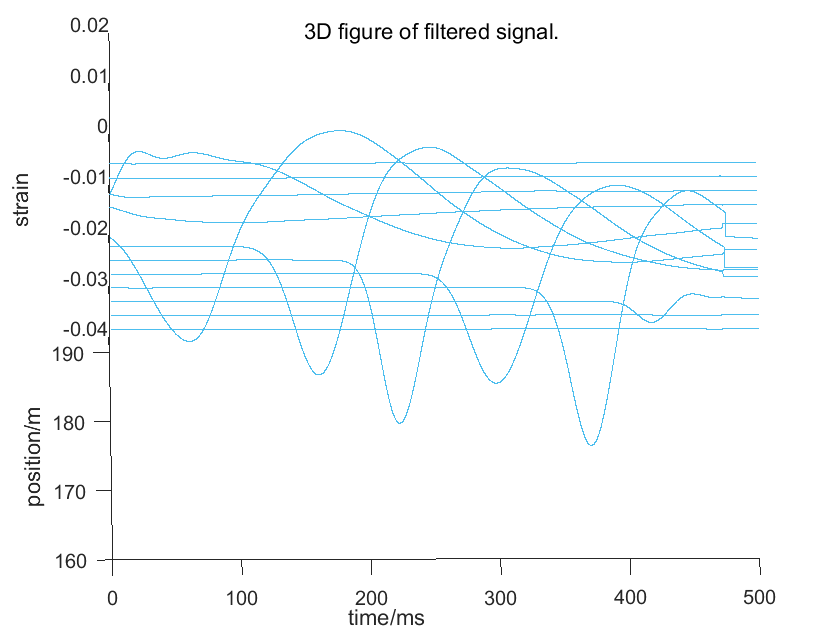

ax1 = axes(figure);
plot3D(ax1, strainFilterMat(arr, :), position(arr), time);   title(ax1, '3D figure of filtered signal. ');

view([-0.2960 34.2796])

We take the fast Fourier transform of the filtered strain data

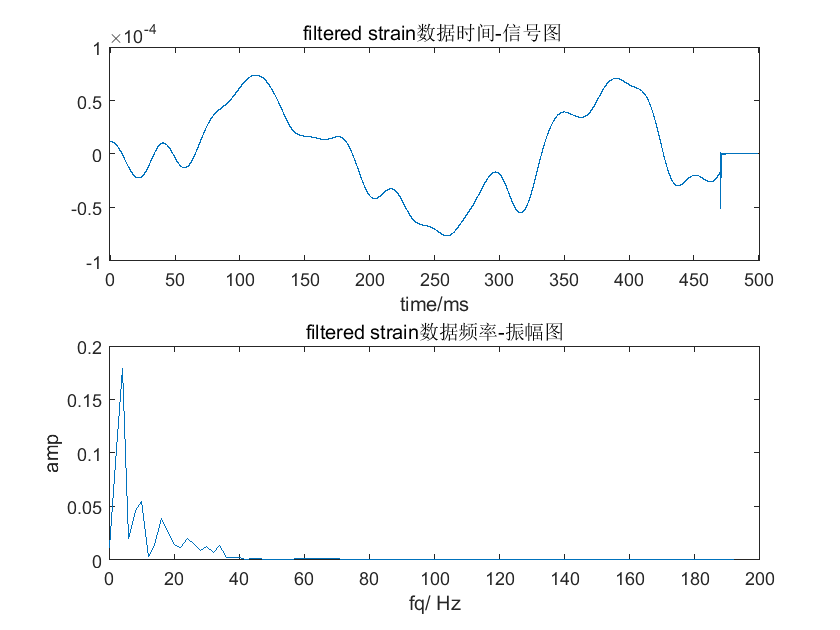

[ampMat1, ~, ~] = fftfunc(strainFilterMat(count0, :), time, 'filtered strain');

rms values before and after filtering.

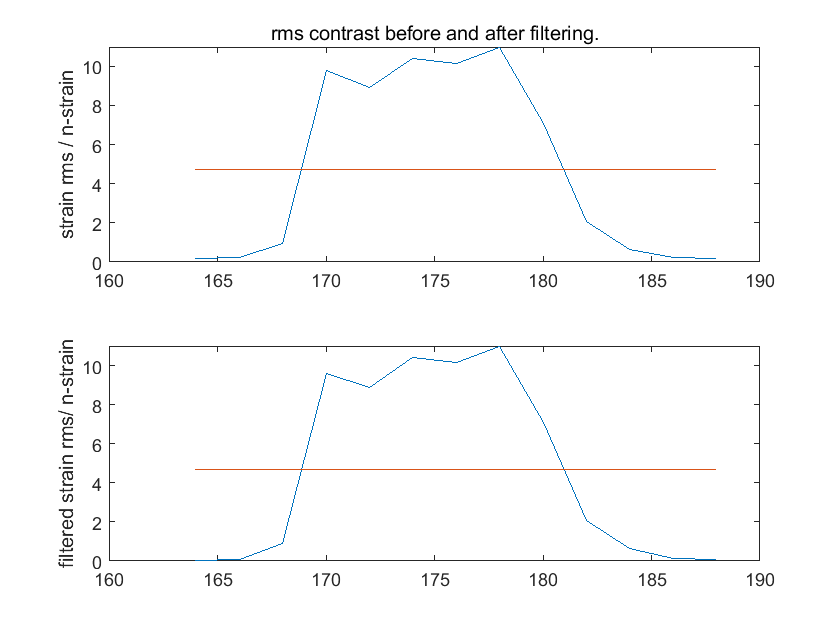

tmp1 = rms(strainMat(arr, :), 2)*1000;
tmp2 = rms( strainFilterMat(arr, :), 2)*1000;
figure; sp = 2;
subplot(sp, 1, 1);
plot(arr, tmp1);  hold on; 
plot(arr, mean(tmp1)*ones(1, length(arr)));
ylabel('strain rms / n-strain');
title('rms contrast before and after filtering.');
subplot(sp, 1, 2);
plot(arr, tmp2);   hold on; 
plot(arr, mean(tmp2)*ones(size(arr)));
ylabel('filtered strain rms/ n-strain');

cumulative noise 

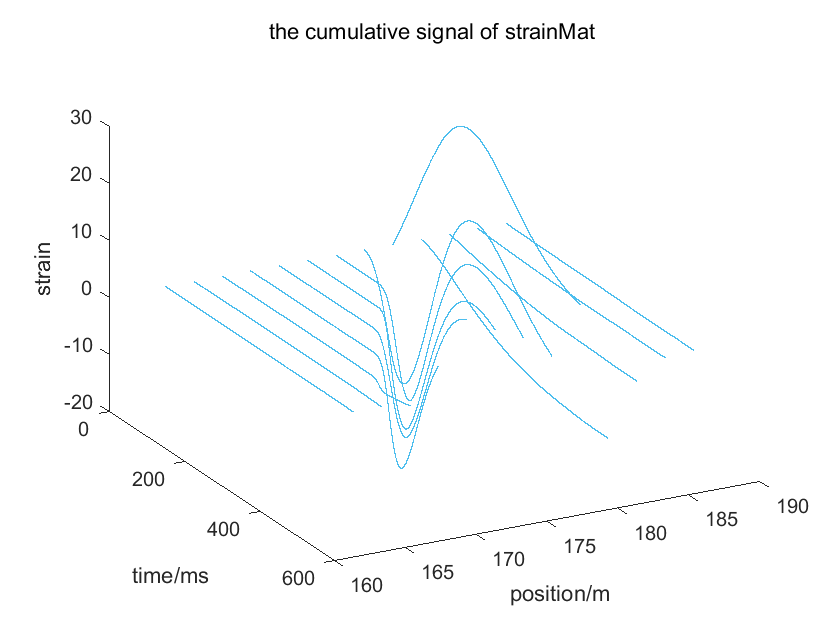

[sMat1, sMat2] = deal(zeros(size(strainMat)));
sMat1(:, 1) = strainMat(:, 1);
sMat2(:, 1) = strainFilterMat(:, 1);
for i = 2: length(time)
    sMat1(:, i) = sMat1(:, i-1) + strainMat(:, i);
    sMat2(:, i) = sMat2(:, i-1) + strainMat(:, i);
 end
ax1 = axes(figure);   plot3D(ax1, sMat1(arr, :), arr, time); 
title(ax1, 'the cumulative signal of strainMat ');

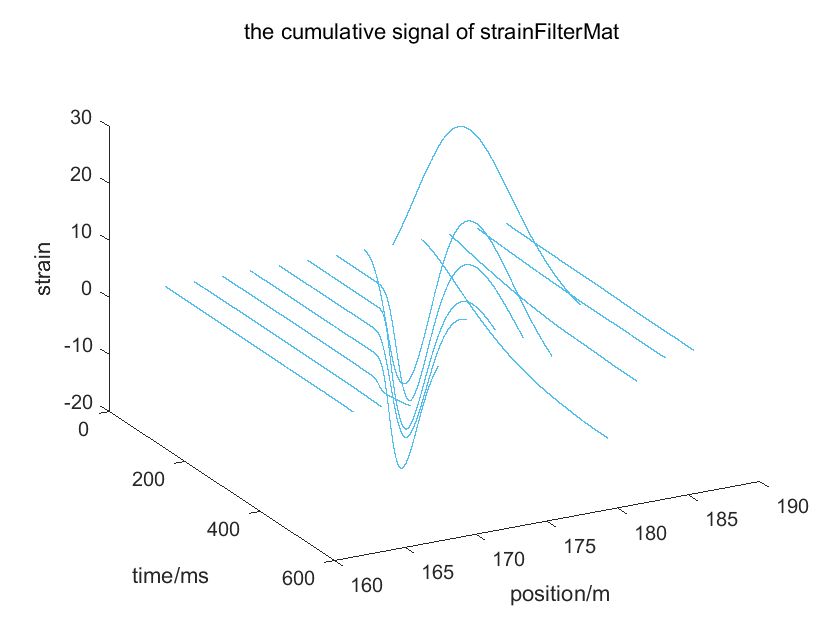


ax1 = axes(figure);   plot3D(ax1, sMat2(arr, :), arr, time); 
title(ax1, 'the cumulative signal of strainFilterMat ');

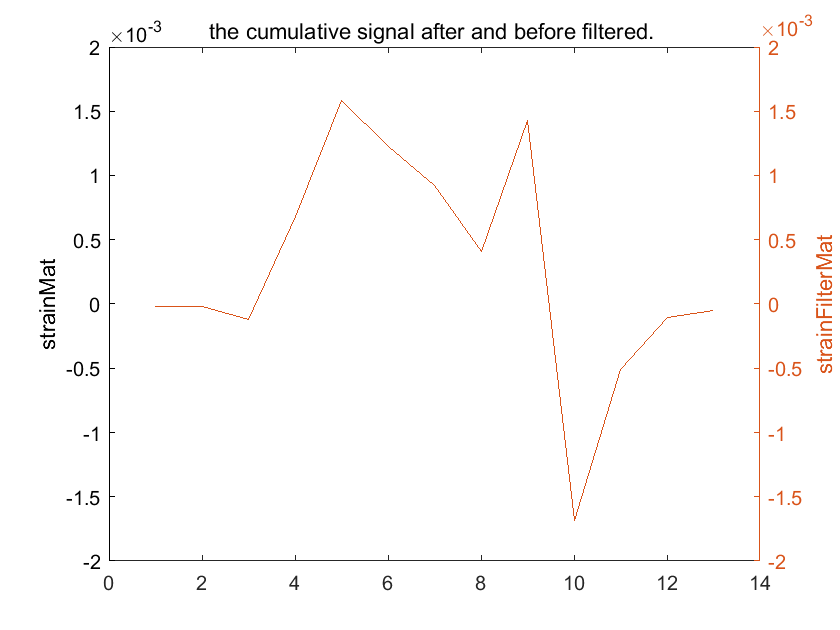


figure;
plot(sMat1(arr, end)/length(time));  ylabel('strainMat');
yyaxis right; 
plot(sMat2(arr, end)/length(time));  ylabel('strainFilterMat');
title('the cumulative signal after and before filtered. ');

noise distribution. 

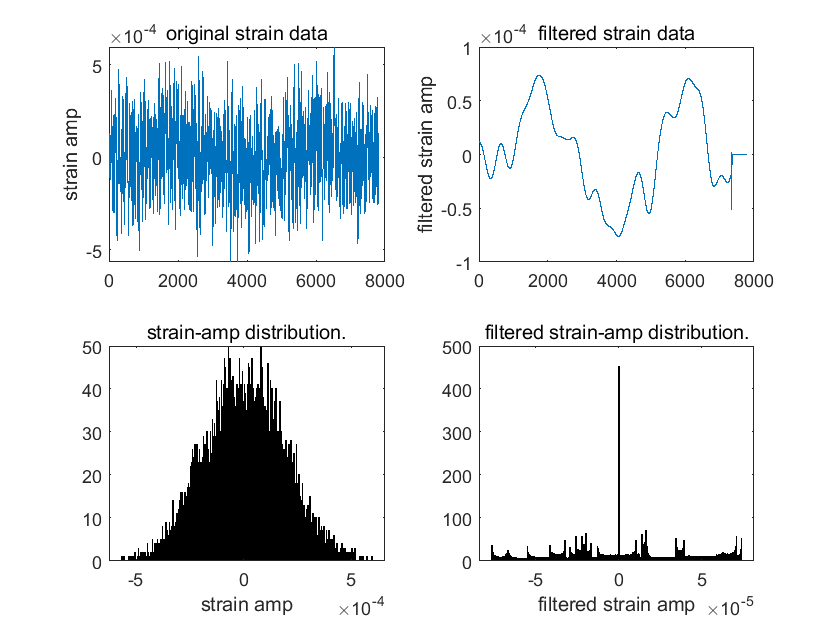

figure;
meanS = mean(strainMat(arr, :), 2); 
strain1 = strainMat(count0, :);
strain2 = strainFilterMat(count0, :);
sp = 2;
subplot(sp, 2, 1);
plot(strain1); ylabel('strain amp');
title('original strain data')
subplot(sp, 2, 3);
histogram(strain1, 500);  xlabel('strain amp');
title('strain-amp distribution.');
% 
subplot(sp, 2, 2);
plot(strain2); ylabel('filtered strain amp');
title('filtered strain data');
subplot(sp, 2, 4);
histogram(strain2, 500);  xlabel('filtered strain amp');
title('filtered strain-amp distribution.');

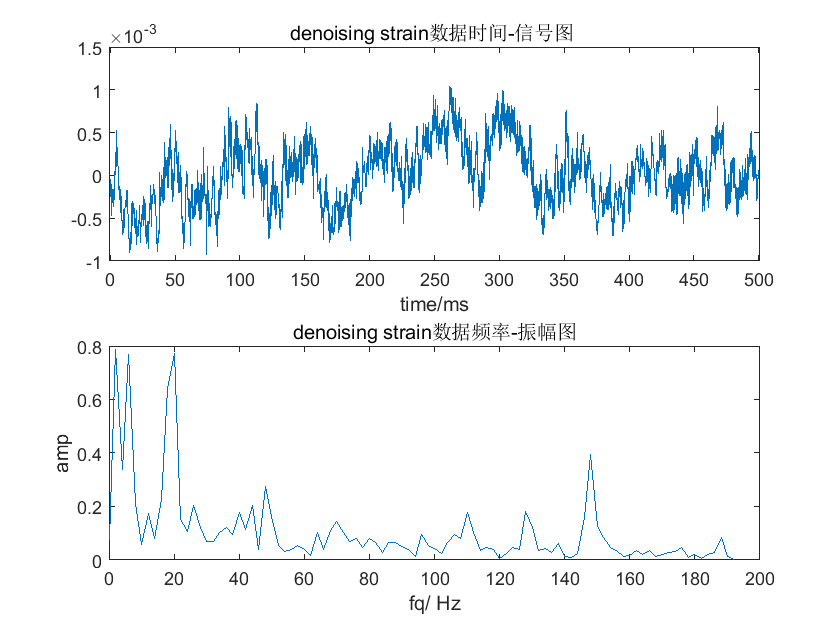

% return;
% -----------------------------------------------------------------------------------------------------
strain = strainMat(2, :);
% Do fft on raw audio data.
[temp, ~, ~] = fftfunc(strain, time, 'denoising strain');

strainFft = abs(temp);
%

## low pass filter.

the frequency of each point

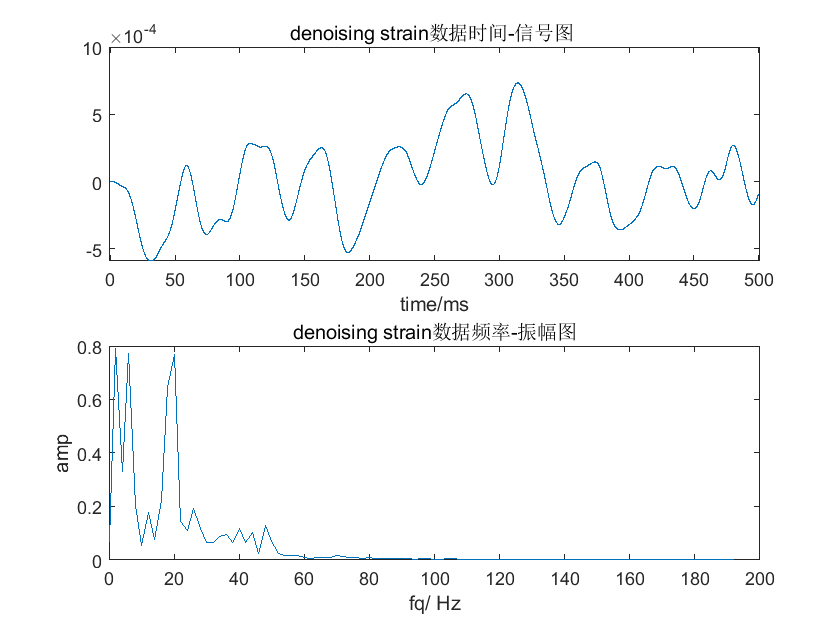

fn = length(frequencyArray0);
% Low-pass filtering on raw data.
f1 = 20;   f2 = 100;  nOrder = 4;
% Band-pass filtering on raw data.
[b, a] = butter(nOrder, 2*f1/fn);
% [b, a] = butter(nOrder, [2*f1/fn, 2*f2/fn],'bandpass');
% freqz(b, a);
%
strain1 = filter(b, a, strain);
% Do fft on filtered audio data.
[temp, ~, ~] = fftfunc(strain1, time, 'denoising strain');

strainFft1 = abs(temp);

Visualization.

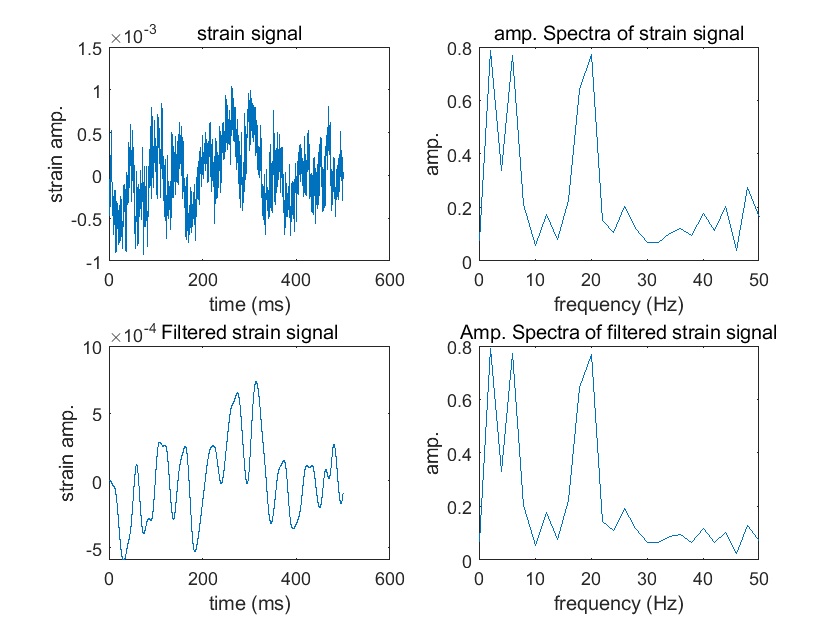

figure(1);
subplot(2, 2, 1);
plot(time, strain);
xlabel('time (ms)');
ylabel('strain amp.');
title('strain signal');
% set(gca, 'fontsize', 20);
hold on;
subplot(2, 2, 2);
plot(frequencyArray0, strainFft);
xlim([0, 50])
xlabel('frequency (Hz)')
ylabel('amp.');
title('amp. Spectra of strain signal');
% set(gca, 'fontsize', 20);
hold on;
subplot(2, 2, 3)
plot(time, strain1);
xlabel('time (ms)');
ylabel('strain amp.');
title('Filtered strain signal');
% set(gca, 'fontsize', 20);
subplot(2, 2, 4);
plot(frequencyArray0, strainFft1);
xlim([0, 50]);
xlabel('frequency (Hz)')
ylabel('amp.');
title('Amp. Spectra of filtered strain signal');

% set(gca, 'fontsize', 20);